# Linear Regression with Categorical Covariates

Perform a regression with categorical covariates using categorical arrays and fitlm.

## **Load sample data.**

load carsmall

## **Plot grouped data.**

Draw a scatter plot of MPG against Weight, grouped by model year.

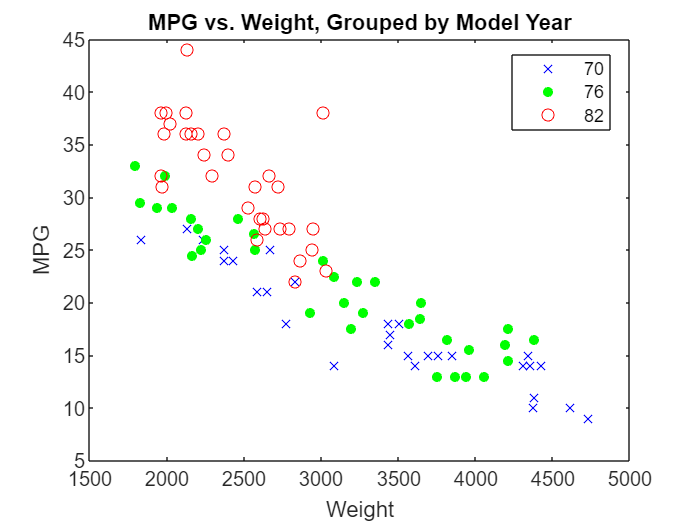

figure()
gscatter(Weight,MPG,Model_Year,'bgr','x.o')
title('MPG vs. Weight, Grouped by Model Year')

## **Create table and categorical array.**

Create a table that contains the variables MPG, Weight, and Model_Year. Convert the variable Model_Year to a categorical array.

cars = table(MPG,Weight,Model_Year);
cars.Model_Year = categorical(cars.Model_Year);

## **Fit a regression model.**

Fit a regression model using fitlm with MPG as the dependent variable, and Weight and Model_Year as the independent variables. Because Model_Year is a categorical covariate with three levels, it should enter the model as two indicator variables.

The scatter plot suggests that the slope of MPG against Weight might differ for each model year. To assess this, include weight-year interaction terms.

The proposed model is

***E*****(*****MPG*****)=*****β*****0+*****β*****1*****Weight*****+*****β*****2*****I*****[1976]+*****β*****3*****I*****[1982]+*****β*****4*****Weight*****×*****I*****[1976]+*****β*****5*****Weight*****×*****I*****[1982],**

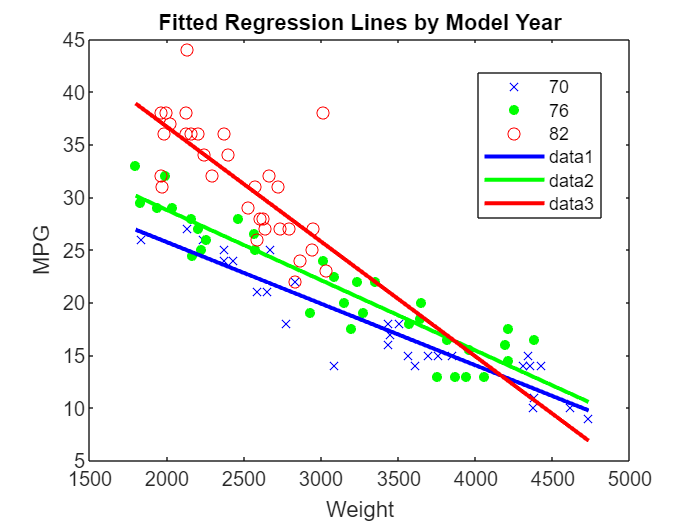

fit = fitlm(cars,'MPG~Weight*Model_Year');
w = linspace(min(Weight),max(Weight));

figure()
gscatter(Weight,MPG,Model_Year,'bgr','x.o')
line(w,feval(fit,w,'70'),'Color','b','LineWidth',2)
line(w,feval(fit,w,'76'),'Color','g','LineWidth',2)
line(w,feval(fit,w,'82'),'Color','r','LineWidth',2)
title('Fitted Regression Lines by Model Year')

## Test for different slopes.

Test for significant differences between the slopes. This is equivalent to testing the hypothesis

H0: β4=β5=0

HA: βi≠0  for  at least  one  i.

anova(fit)

ans = 4×5 table
                         SumSq     DF    MeanSq      F         pValue  
                         ______    __    ______    ______    __________

    Weight               2050.2     1    2050.2    263.87    3.2055e-28
    Model_Year           807.69     2    403.84    51.976    1.2494e-15
    Weight:Model_Year    81.219     2    40.609    5.2266     0.0071637
    Error                683.74    88    7.7698                        


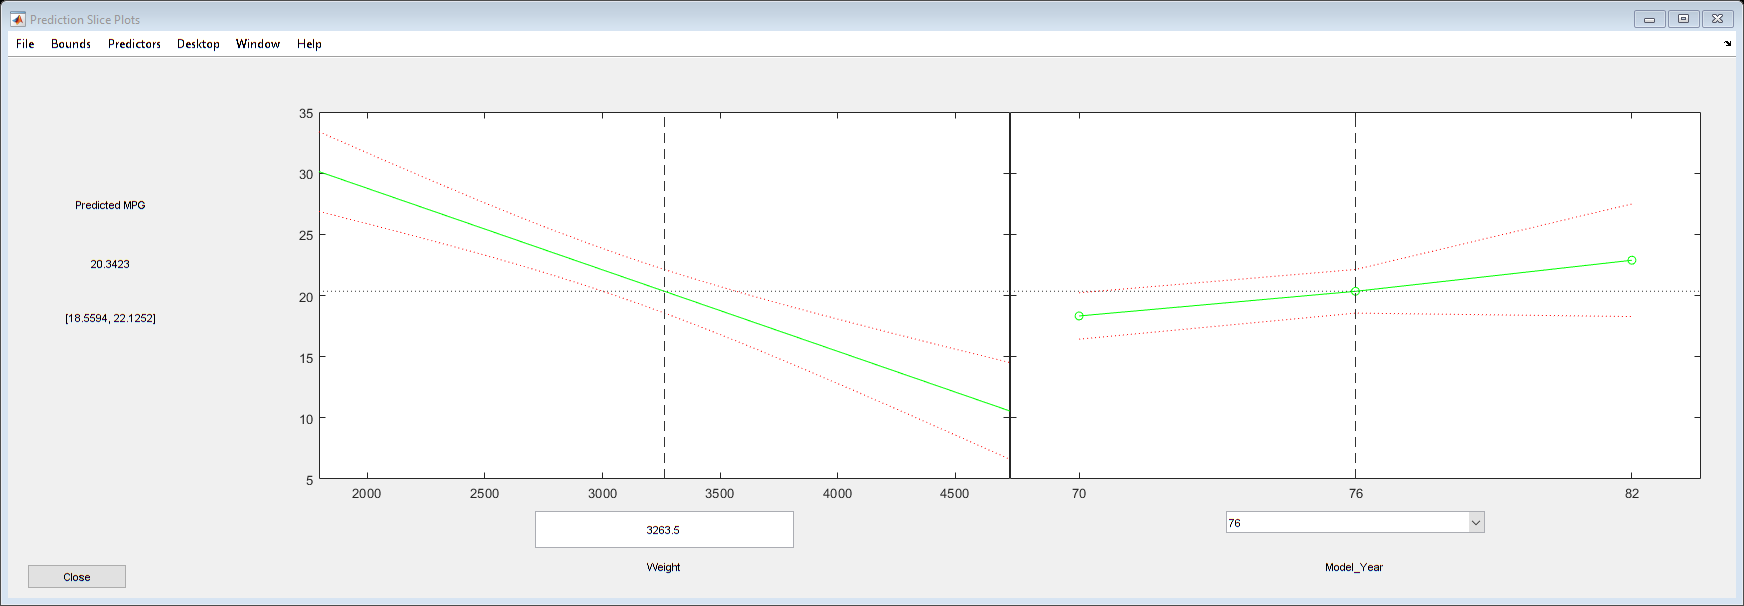

figure
plotSlice(fit)